# Sessió 10

## 1. App Classification Learner

L’objectiu d’aquesta pràctica és aprendre a classificar mostresa partir dels seus vectors de caracterìstiques. Usarem la App Classification learner de Matlab. Trobareu la informació necessària a:

https://uk.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html

https://uk.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html

Podeu utilitzar el dataset Fisher iris (tot un clàssic) i experimentar amb diferents classificadors. En acabar heu de ser capaços de:

- Tunnejar correctament els paràmetres d’un classificador

- Probar diferents classificadors i escollir-ne els que donin millors resultats

- Fer experiments amb rigor (p.ex: cross-validation)

- Presentar els resultats de forma correcta ( corba RoC, matriu de confusió...)

fishertable = readtable('fisheriris.csv');
view(trainedModel.ClassificationTree,'Mode','graph');
yfit = trainedModel.predictFcn(fishertable);


## 2. Classificació automàtica d’espècies arbòries

Un cop domineu la app Clasification learner, es planteja un problema de classificació amb imatges reals. Dins la tasca corresponent a la sessió 10 a Atenea, trobareu imatges de fulles de roure, faig i plàtan. Entreneu varios classificadors per aquestes tres espècies usant com a vectors de característiques els seus descriptors de Fourier. Es demana un informe (en pdf) que inclogui el codi usat per a obtenir els descriptors, la descripció dels experiments realitzats, els classificadors que han funcionat millor i els resultats obtinguts. Indiqueu quines caracaterístiques del vector són necessàries per a la correcta classificació, i quines no són significatives.

Al trabajar con los descriptores de Fourier de las respectivas imagenes, se nos planteó el dilema de usar el modulo de los descriptores odividir los descriptores, que son números complejos, en dos partes, real e imaginaria.

Haremos pruebas de ambos casos y decidiremos cual nos dá un mejor resultado.

## Clasificación 

Primero estudiaremos los resultado en función del número de descriptores (5, 10 , 50 ,100, 1000)

Para las pruebas, hemos decidido dividir nuestros datos en 2 conjuntos: Train y Test.

Test es un 30% del total de los datos y serán escogidos aleatoriamente en cada prueba, sin embargo, sabremos que del 30%, el primer tercio son Arce, el segundo tercio son Haya y el último tercio son Roble.

### Clasificación usando parte real e imaginaria

- Usando 5 descriptores nos da los siguientes resultados:

            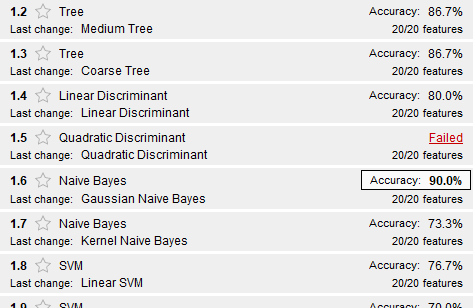

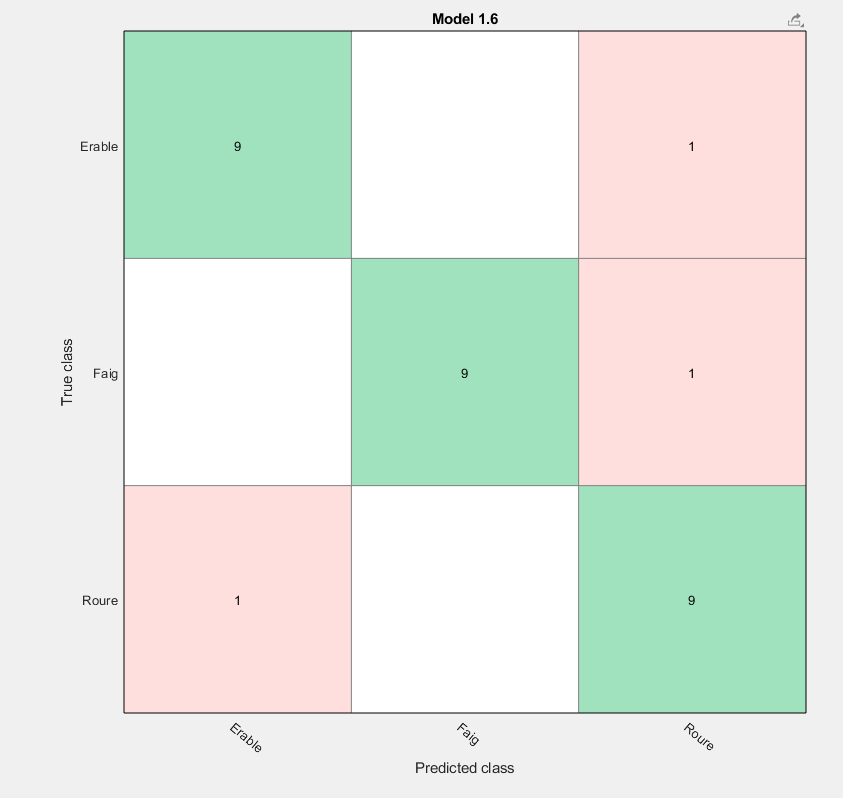

Haremos una prueba con los datos Test:

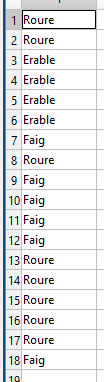

Como se puede observar y sabiendo los resultados correctos expuestos arriba, hay un gran porcentaje de fallos, un 20% aproximadamente. 

- Usando 20 descriptores nos da los siguientes resultados:

### Clasificación usando el módulo

- Usando 5 descriptores nos da los siguientes resultados:

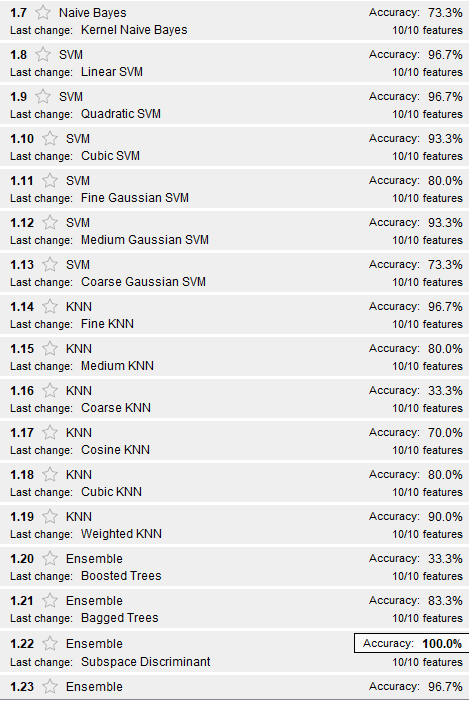

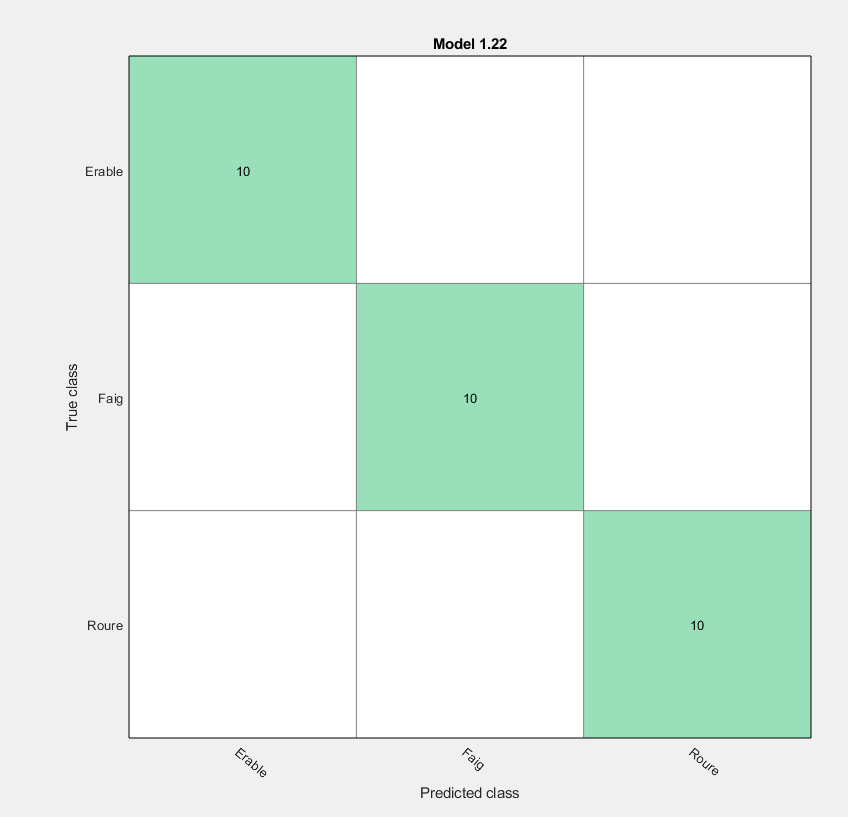

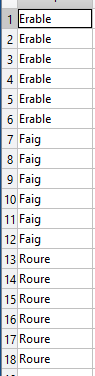

Buenos resultados aunque es posible debido a la poca cantidad de datos

- Usando 20 descriptores nos da los siguientes resultados:

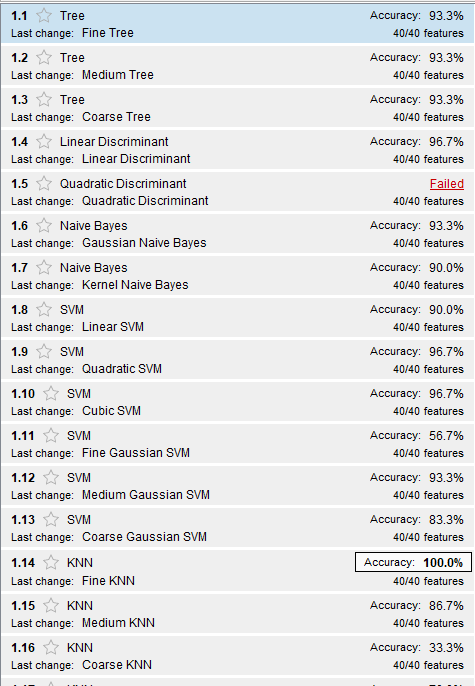

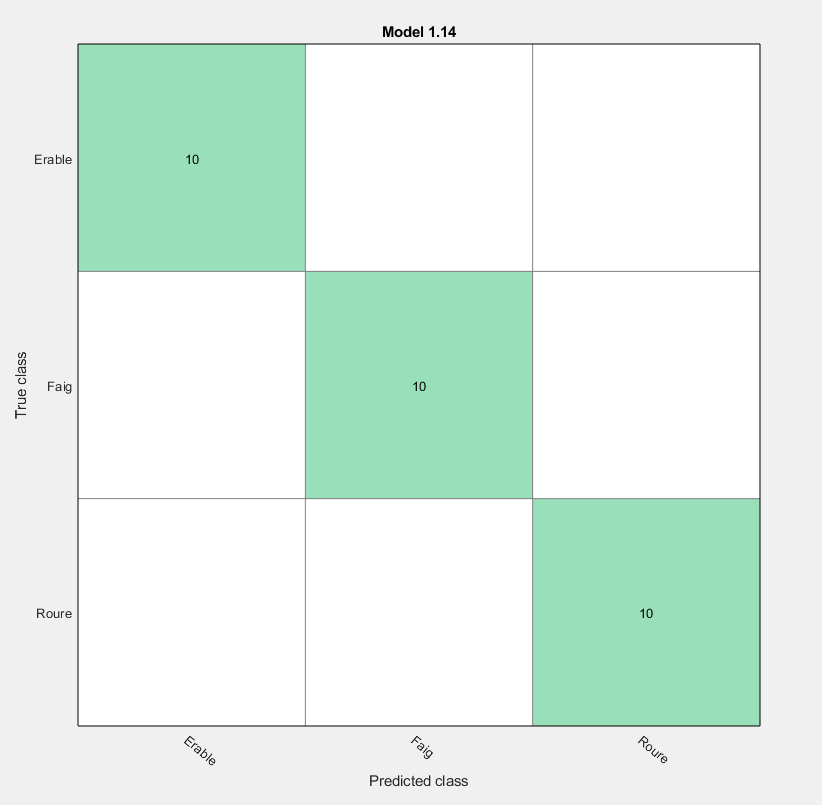

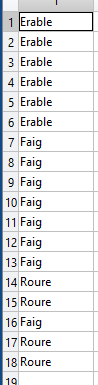

- Usando 50 descriptores nos da los siguientes resultados:

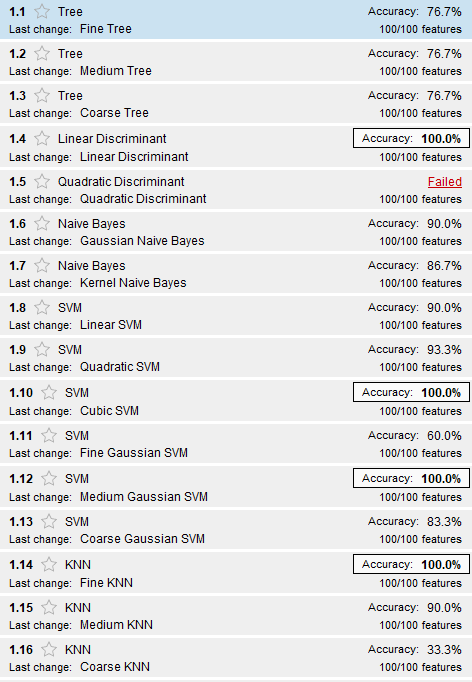

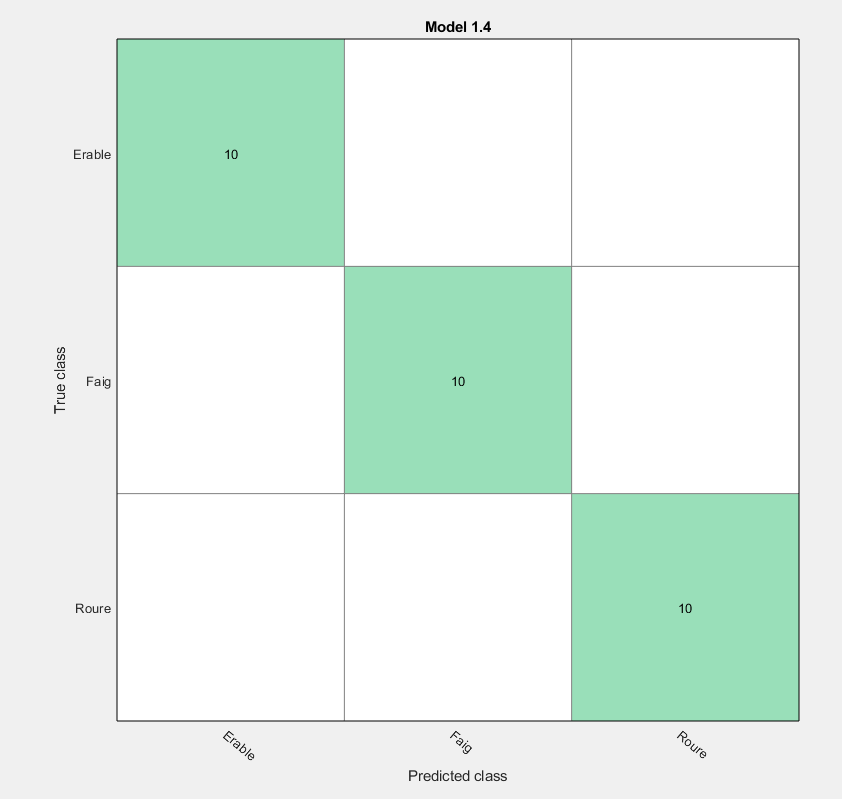

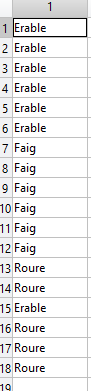

- Usando 75 descriptores nos da los siguientes resultados:

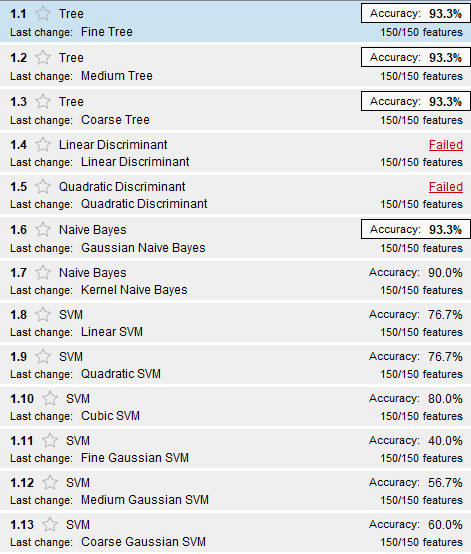

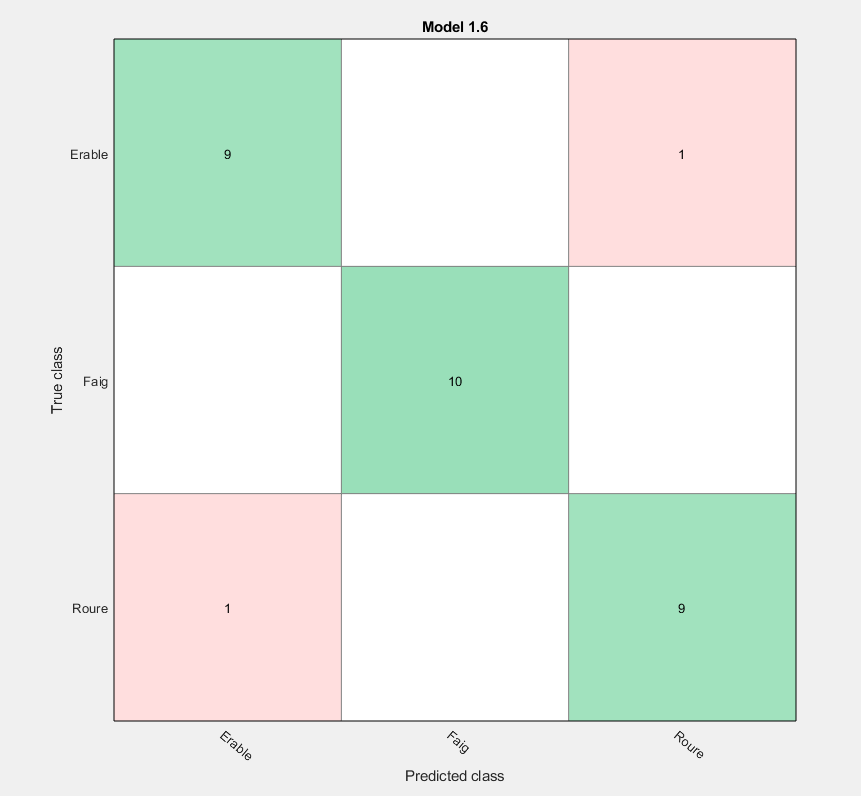

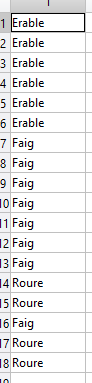

%im = imread('l2nr002.jpg')
%[descriptor] = descriptor_fourier(im,nan)
p = randperm(16);
train = p(1:10);
test = p(11:16);
[T1Train, T2Train, dataTrain] = getdataexercise2(train)

data =   -27.6601    6.7120    7.0322    7.0347    7.1219    6.6904    7.1124    6.3540    6.2446    5.0072    6.1443    4.6167    5.7963    5.8049    5.9402    3.6850    5.4550    5.4700    3.9228    5.4717    3.2588    4.6316    4.8689    4.0681    5.1878    2.9713    4.6249    3.3432    5.8912    4.5047    5.6707    5.5866    6.5429    6.8854    6.7299    6.4209    5.7175    7.2545    7.3716    9.6289
    3.6478    6.2503    6.0083    5.1783    6.1637    6.3466    5.4748    4.7473    5.3263    5.6686    4.4668    6.0896    5.2029    4.7913    4.3114    1.9668    4.6097    3.9461    4.3506    3.8756    3.5457    1.0728    2.6944    3.2281    4.0573    3.3928    3.5928    4.4014    5.1844    4.9419    4.4034    3.5646    4.7337    4.1330    6.1945    5.4787    5.4108    5.1376    6.6701    8.9463
  -25.9204    9.5454    9.4655    9.2270    8.4868    8.3080    7.9425    7.0082    6.5313    6.9162    7.3481    6.9771    6.9683    6.9392    7.0887    6.9436    5.8652    5.2320    5.0055 

T1Train = 30×2 table
        Var1         namesleaf
    _____________    _________

    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   


T2Train = 30×2 table
        Var1         namesleaf
    _____________    _________

    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   


dataTrain =   -27.6601    6.7120    7.0322    7.0347    7.1219    6.6904    7.1124    6.3540    6.2446    5.0072    6.1443    4.6167    5.7963    5.8049    5.9402    3.6850    5.4550    5.4700    3.9228    5.4717    3.2588    4.6316    4.8689    4.0681    5.1878    2.9713    4.6249    3.3432    5.8912    4.5047    5.6707    5.5866    6.5429    6.8854    6.7299    6.4209    5.7175    7.2545    7.3716    9.6289
    3.6478    6.2503    6.0083    5.1783    6.1637    6.3466    5.4748    4.7473    5.3263    5.6686    4.4668    6.0896    5.2029    4.7913    4.3114    1.9668    4.6097    3.9461    4.3506    3.8756    3.5457    1.0728    2.6944    3.2281    4.0573    3.3928    3.5928    4.4014    5.1844    4.9419    4.4034    3.5646    4.7337    4.1330    6.1945    5.4787    5.4108    5.1376    6.6701    8.9463
  -25.9204    9.5454    9.4655    9.2270    8.4868    8.3080    7.9425    7.0082    6.5313    6.9162    7.3481    6.9771    6.9683    6.9392    7.0887    6.9436    5.8652    5.2320    5.

[T1Test, T2Test, dataTest] = getdataexercise2(test)

data =     3.8587    7.0293    7.6136    7.5930    7.1094    7.4845    4.9829    6.2418    5.6200    5.5725    5.0752    6.2347    5.0658    6.6293    5.4352    2.6575    4.7929    5.6931    5.5504    3.4389    4.5714    5.0803    2.8893    4.4056    3.8747    5.8109    4.6003    5.7225    4.1733    5.1829    5.7099    5.5602    5.0803    7.1225    5.2826    6.8364    6.1732    6.6553    7.5762    9.7983
  -27.3793    6.7368    6.4260    4.3216    6.5274    6.2917    4.9732    6.1190    5.1771    4.5162    4.4639    5.9595    5.4679    5.3043    3.2120    5.6779    5.2905    4.0601    3.9747    4.1283    1.8916    1.8543    4.6502    4.0668    4.1886    3.9295    4.1180    4.8092    5.1374    5.2299    4.1365    5.0065    5.4989    4.8188    6.3768    5.9411    5.8922    5.0392    6.7115    9.2594
    4.2374    7.9803    7.6499    5.5623    7.1377    7.1419    6.4169    6.8696    6.5860    5.6211    6.5973    6.4397    6.2955    6.6250    6.5223    6.5752    6.2874    5.9071    5.4322 

T1Test = 18×2 table
        Var1         namesleaf
    _____________    _________

    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Erable" 
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Faig"   
    [1×80 double]    "Roure"  
    [1×80 double]    "Roure"  
    [1×80 double]    "Roure"  
    [1×80 double]    "Roure"  


T2Test = 18×2 table
        Var1         namesleaf
    _____________    _________

    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Erable" 
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Faig"   
    [1×40 double]    "Roure"  
    [1×40 double]    "Roure"  
    [1×40 double]    "Roure"  
    [1×40 double]    "Roure"  


dataTest =     3.8587    7.0293    7.6136    7.5930    7.1094    7.4845    4.9829    6.2418    5.6200    5.5725    5.0752    6.2347    5.0658    6.6293    5.4352    2.6575    4.7929    5.6931    5.5504    3.4389    4.5714    5.0803    2.8893    4.4056    3.8747    5.8109    4.6003    5.7225    4.1733    5.1829    5.7099    5.5602    5.0803    7.1225    5.2826    6.8364    6.1732    6.6553    7.5762    9.7983
  -27.3793    6.7368    6.4260    4.3216    6.5274    6.2917    4.9732    6.1190    5.1771    4.5162    4.4639    5.9595    5.4679    5.3043    3.2120    5.6779    5.2905    4.0601    3.9747    4.1283    1.8916    1.8543    4.6502    4.0668    4.1886    3.9295    4.1180    4.8092    5.1374    5.2299    4.1365    5.0065    5.4989    4.8188    6.3768    5.9411    5.8922    5.0392    6.7115    9.2594
    4.2374    7.9803    7.6499    5.5623    7.1377    7.1419    6.4169    6.8696    6.5860    5.6211    6.5973    6.4397    6.2955    6.6250    6.5223    6.5752    6.2874    5.9071    5.4

%view(trainedModel.ClassificationTree,'Mode','graph');

yfit = trainedModel.predictFcn(T2Test);

function [T1, T2, data] = getdataexercise2(listaNum)
    nDesc = 20;
    descriptorsComp = [];
    descriptorsMod = [];
    namesleaf = [];
    images = ["l2nr0", "l15nr0", "l4nr0"];
    fulles = ["Erable", "Faig", "Roure"];
    for k = 1:length(images)
        image = images(k);
        for i = listaNum
            if i < 10
                im = imread(strcat(fulles(k),'/',image ,'0', int2str(i) ,'.jpg'));
            else
                im = imread(strcat(fulles(k),'/',image ,int2str(i) ,'.jpg'));
            end
            [descriptorComp,descriptorMod] = descriptor_fourier(im, nDesc);
            descriptorsComp = [descriptorsComp; descriptorComp];
            descriptorsMod = [descriptorsMod; descriptorMod];
            namesleaf = [namesleaf; fulles(k)];
        end
    end
    data = descriptorsMod
    T1 = table(double(descriptorsComp), namesleaf);
    T2 = table(double(descriptorsMod), namesleaf);
    writetable(T1,'resultado1.csv');
    writetable(T2,'resultado2.csv');
end


function [descriptorDiv,descriptor] = descriptor_fourier(im, Ndescriptors)
    [d1 d2 d3] = size(im);
    if (d3 == 3)
        im = rgb2gray(im);
    end
    im =im2bw(im, graythresh(im)); % Binarització per Otsu
    im = imcomplement(im);
    im=imresize(im,1/16);
    % obtenim el contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    % B conté les coordenades
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    descriptor=fft(s);
    % Obtenim el 
    if (~isnan(Ndescriptors))
        descriptor = [descriptor(1:Ndescriptors);descriptor(end-Ndescriptors+1:end)];
        descriptorDiv = [real(descriptor); imag(descriptor)];
    end
    descriptor = log(abs(descriptor));
    descriptor = descriptor';
    descriptorDiv = descriptorDiv';
end